# Predecir velocidad verdadera a partir de otros sensores

Este ejemplo muestra cómo utilizar datos históricos para entrenar un modelo de regresión que es capaz de predecir la velocidad verdadera (TAS, por sus siglas en inglés) de un vuelo desde mediciones de otros sensores. Este tipo de modelos pueden ser útiles en aplicaciones de control donde puede ser deseable usar un modelo de regresión como un estimador de estado para estados no observables, o costosos de observar. Estos modelos pueden ser útiles en aplicaciones de control donde puede ser conveniente usar un modelo de regresión como estimador de estado no lineal para un estado no observable o de observación costosa. Estos tipos de modelos también pueden emplearse como modelos sustitutos en simulaciones y estudios de mercado, cuando un modelo basado en la física es demasiado complejo de crear o su simulación requiere demasiado tiempo.

## Importar datos de Excel 

Comenzaremos leyendo los datos con código generado con la herramienta **Import Tool **(`importFlightData`). También eliminamos los datos registrados cuando la aeronave estaba detenida en tierra, ya que no serán útiles para predecir la velocidad del aire.

FlightData = importFlightData("FlightData.xlsx");

FlightData = FlightData(FlightData.TrueAirSpeed >= 20,:)

summary(FlightData)

## Visualiza los datos

Podemos ver la trayectoria del vuelo mediante un `geoplot` mostrando la latitud y longitud. 

Para ellos usaremos una **Live Task ** llamada **Create Plot**.

% Create geoplot of FlightData.LatitudePosition and FlightData.LongitudePosition

% Create geoplot of selected data
h2 = geoplot(FlightData.LatitudePosition,FlightData.LongitudePosition,"LineStyle","--");

% Add title
title("FlightData.LatitudePosition vs. FlightData.LongitudePosition")


Puedes modificar el código generado por la **Task **y modificarlo. Por ejemplo, podemos cambiar el color y grosor de la línea. También podemos cambiar la base del mapa usando el `comando geobasemap`

Algunos de los sensores parecen tener interrupciones que necesitaremos depurar. Visualizaremos `FlightData.OilPressure` y `FlightData.OilTemperature`.

figure
% Create plot of FlightData.Time and FlightData.OilPressure
plot(FlightData.Time,FlightData.OilPressure,"DisplayName","OilPressure");

hold on
% Create plot of FlightData.Time and FlightData.OilTemperature
plot(FlightData.Time,FlightData.OilTemperature,"DisplayName","OilTemperature");
hold off

legend

## Limpiar los datos del sensor

Usa la app de limpieza de datos (**Data Cleane**r) en la pestaña APPS para eliminar las interrupciones del sensor de presión y temperatura del aceite y generamos una función llamada `cleanOilSensors`.

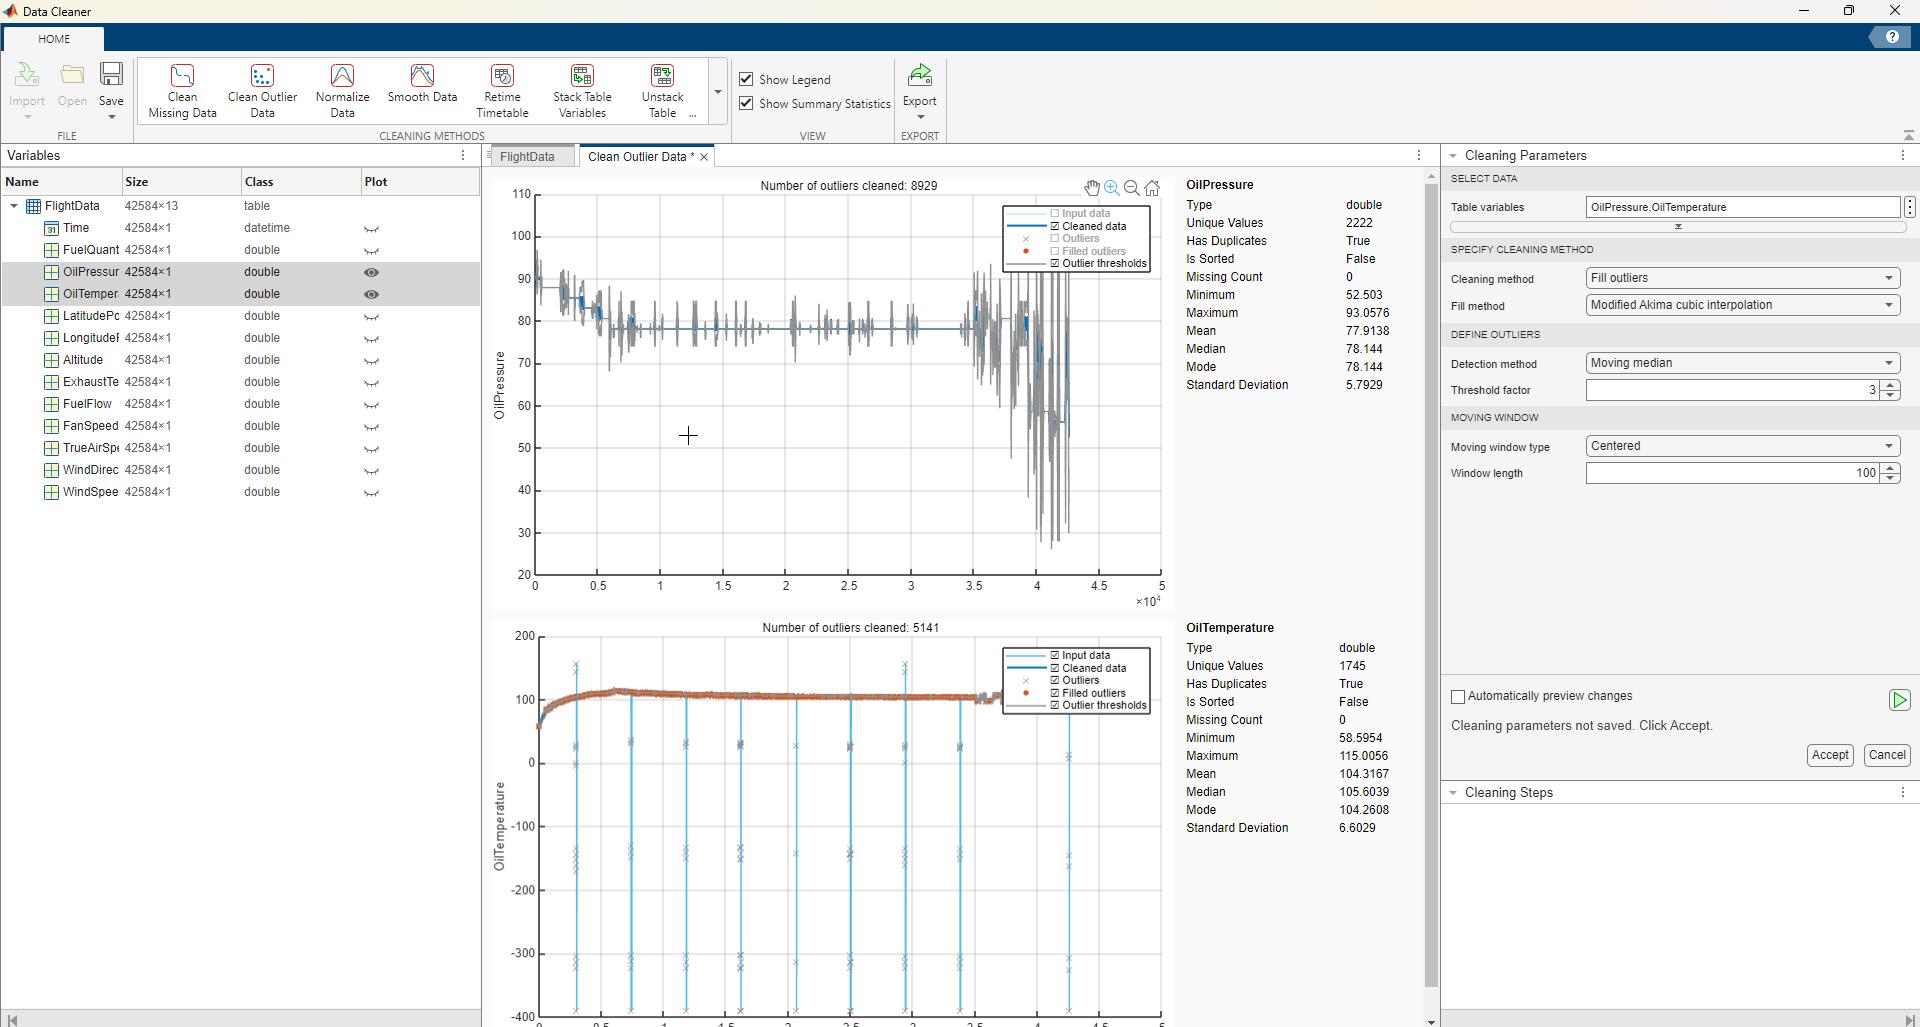

FlightDataClean = cleanOilSensors(FlightData);


figure
% Create plot of FlightDataClean.Time and FlightDataClean.OilPressure
plot(FlightDataClean.Time,FlightDataClean.OilPressure,"DisplayName","OilPressure");

hold on
% Create plot of FlightDataClean.Time and FlightDataClean.OilTemperature
plot(FlightDataClean.Time,FlightDataClean.OilTemperature,"DisplayName","OilTemperature");
hold off

legend

## Modelado de la velocidad verdadera del aire

Podemos modelar la TAS con un modelo de regresión entrenado en la aplicación **Regression Learner**. Usaremos un árbol de decisión combinado (bagged decision tree) con la configuración predeterminada, que produce resultados muy precisos con validación cruzada. Normalmente, en un flujo de trabajo de aprendizaje automático usaríamos un conjunto de prueba separado para verificar los resultados, pero en este caso lo omitiremos por brevedad.

regressionLearner

Usando el código generado a partir de la aplicación **Regression Learner**:

rng(1) % reproducibility
mdl = trainTASModel(FlightDataClean)
PredictedAirSpeed = mdl.predictFcn(FlightDataClean);

## Importancia de los predictores

**¿Qué mediciones son importantes para hacer predicciones?** Uno de los beneficios del modelo de árbol de decisión combinado (bagged decision tree) es que proporciona automáticamente una medida de la importancia de cada predictor.

En este caso,` FuelFlow` es el predictor más importante, seguido por `WindDirection`, `WindSpeed `y `FanSpeed`.

figure
bar(mdl.RegressionEnsemble.predictorImportance)
xticklabels(mdl.RequiredVariables)